# Getting Started with Fast Visualization

## Main primitive types to render

Here is a list of the basic primitives you can render in an fvFigure:

- [Pointclouds](matlab:open('./Pointclouds.mlx'))

- [Lines](matlab:open('./Lines.mlx'))

- [Images](matlab:open('./Images.mlx'))

- [Meshes](matlab:open('./Meshes.mlx'))

- [Surfaces](matlab:open('./Surfaces.mlx'))

- [Text](matlab:open('./Text.mlx'))

By default, the primitive is created in the current fvFigure. You can attach the new primitive to another fvFigure or another existing primitive by specifying it as the first argument.

Example:

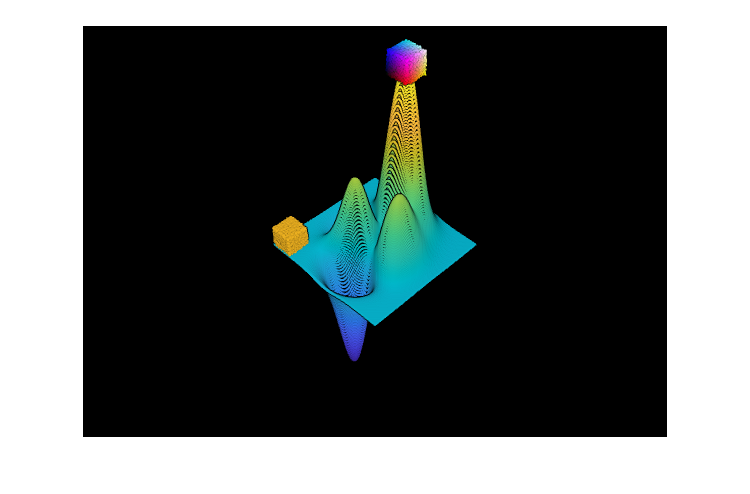

f = fvclear; % get and clear the current figure

pc1 = fvPointcloud; % no argument defaults on peaks example

fvhold on

% create a rand cube and place it at the corner of pc1
xyz = rand(10000,3);
pc2 = fvPointcloud(xyz);
pc2.Translate([-3 -3 0]);

% create a rand color cube attached to pc1 at the top
col = xyz;
pc3 = fvPointcloud(pc1,xyz,col);
[~,i] = max(pc1.Coord(:,3));
pc3.Translate(pc1.Coord(i,:)-0.5);
f.Snapshot;

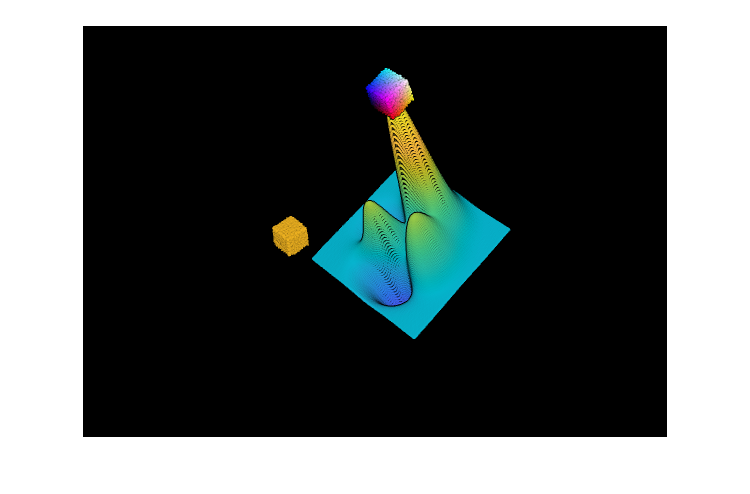


% Rotate and translate pc1
pc1.Rotate([20 0 0],true).Translate([1 1 0]);
f.Snapshot;

pc2 stays at the same place because it is attached to the fvFigure.

pc3 moves with pc1 because it is attached to pc1.